# Non-Isentropic Ramjet Tt3 Design Calculator

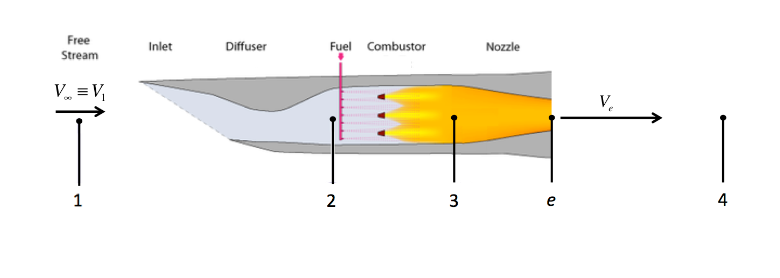

Input

- alt: in m

- eta_d 

- eta_n

- A_e

- M1

- M2

- Tt3

- qf: j/kg

Output

- Overall_efficiency

- Thrust

function [Overall_efficiency, Thrust] = RamjetTt3DesignCalculator(alt, eta_d, eta_n, A_e, M1, M2, qf, Tt3)

## Constants

R = 286.9;
gamma_12= 1.4;
gamma_23= 1.3;
gamma_3e= 1.3;

## State Calculations

### State 1 (module 1)

[T1,P1,~,~]=IsenAltModel(alt);
a1= sqrt(gamma_12*R*T1);
Tt1=TotalToStaticTemperatureRel([],T1,M1,gamma_12);
V1 = M1*a1;


### State 2 (module 2)

Tt2 = Tt1; %no w or q

Pt2 = P1*(1+eta_d*((gamma_12-1.)/2).*M1.^2).^(gamma_12./(gamma_12-1));
P2 = TotalToStaticPressureRel(Pt2,[],M2,gamma_12);


### State 3 (module 3)

Tt3_choked = Tt2*( (1/(2*(gamma_23+1))) * (1/M2^2) * (1+gamma_23*M2^2)^2 * (1+((gamma_23-1)./2).*M2.^2)^-1);

if(Tt3_choked<Tt3)
    Tt3 = Tt3_choked;
    M3 = 1;
    %disp('Combustor Thermally Choked')
else
    fun = @(M3)M3Solver(M3, Tt3, Tt2,M2, gamma_23);
    M3_0 = .5;
    options = optimoptions('fsolve', 'MaxFunctionEvaluations',5000, 'MaxIterations',5000, Display='none');
    M3 = fsolve(fun,M3_0,options);
    %disp('Combustor is not Thermally Choked: Tt3 Materially Limited')
end

q23 = 986*(Tt3-Tt1)+0.5*0.179*(Tt3^2-Tt1^2);
P3 = P2; %const. p heat addition
Pt3 =  TotalToStaticPressureRel([],P3,M3,gamma_23);

### Nozzle (module 4)

#### Is the Nozzle Choked?

Test_Mach_num = sqrt((2/(gamma_3e-1)) * ((eta_n*(1-(P1/Pt3)^((gamma_3e-1)/gamma_3e)))/(1-eta_n*(1-(P1/Pt3)^((gamma_3e-1)/gamma_3e)))));

if (Test_Mach_num<1)
    %disp('Nozzle is not Choked')
    Me = Test_Mach_num;
    Pe =P1;
else 
    %disp('Nozzle is Choked')
    Me = 1;
    Pe = Pt3*(1-(1/eta_n)*((gamma_3e-1)/(gamma_3e+1)))^(gamma_3e/(gamma_3e-1));
end

### Nozzle Exit

Tte = Tt3;
Te =  TotalToStaticTemperatureRel(Tte,[],Me,gamma_3e);
ae = sqrt(gamma_3e*Te*R);
Ve = ae*Me;
mass_flux_exit = (Pe/(R*Te))*Ve*A_e;

## Engine Performance (module 6)

mass_flux_inlet = mass_flux_exit/(1+(q23/qf));
mass_flux_fuel = mass_flux_exit-mass_flux_inlet;
f = mass_flux_fuel/mass_flux_inlet;
Thrust = mass_flux_inlet*((1+f)*Ve-V1) + (Pe-P1)*A_e;

Veq = Ve + (Pe-P1)*(A_e/mass_flux_exit);
Propulsive_efficiency = 2/(1+Veq/V1);
Thermal_efficiency = ((mass_flux_exit*.5*Veq^2)-(mass_flux_inlet*.5*V1^2))/(mass_flux_inlet*q23);
Overall_efficiency = Propulsive_efficiency*Thermal_efficiency;
end

function F = M3Solver(M3, Tt3, Tt2,M2, gamma_23)
F = ((M3/M2)^2 * ((1+gamma_23*M2^2)/(1+gamma_23*M3^2))^2 * ((1+((gamma_23-1)./2).*M3.^2)/(1+((gamma_23-1)./2).*M2.^2))) - Tt3/Tt2;
end